# **Batch PCA: Monitoring on time varying data (drifts) with Faults**

clc; clear;
load('monitoring_data.mat')
close all;

plots_dir = fullfile(pwd, 'plots');
if ~exist(plots_dir, 'dir')
    mkdir(plots_dir);
end


## **Model Initialization**

#### Batch PCA is trained once on N=10'000 stationary healthy samples. The model is then applied to the time-varying monitoring dataset.


%% 1. Batch PCA: SVD on Training Data

[U, S, V] = svd(Z, 'econ');

singular_values    = diag(S);
eigenvalues        = singular_values.^2 / (N - 1);
explained_variance = 100 * eigenvalues / sum(eigenvalues);
cum_variance       = cumsum(explained_variance);

q   = 3;
Vq  = V(:, 1:q);

% Training thresholds
scores_train = Z * Vq;
SPE_train    = sum((Z - scores_train * Vq').^2, 2);
T2_train     = sum((scores_train ./ eigenvalues(1:q)') .* scores_train, 2);

SPE_lim = quantile(SPE_train, 0.95);
T2_lim  = (q*(N-1)*(N+1)) / (N*(N-q)) * finv(0.95, q, N-q);

fprintf('q = %d | Explained variance: %.1f%%\n', q, cum_variance(q))

q = 3 | Explained variance: 92.0%


fprintf('SPE limit: %.4f | T2 limit: %.4f\n', SPE_lim, T2_lim)

SPE limit: 1.3466 | T2 limit: 7.8197


## 2. Model Selection and Scree Plot

### **Number of PCs**

#### The number of principal components q is selected via the scree plot. We look for the elbow and verify that **cumulative variance exceeds 90%**.

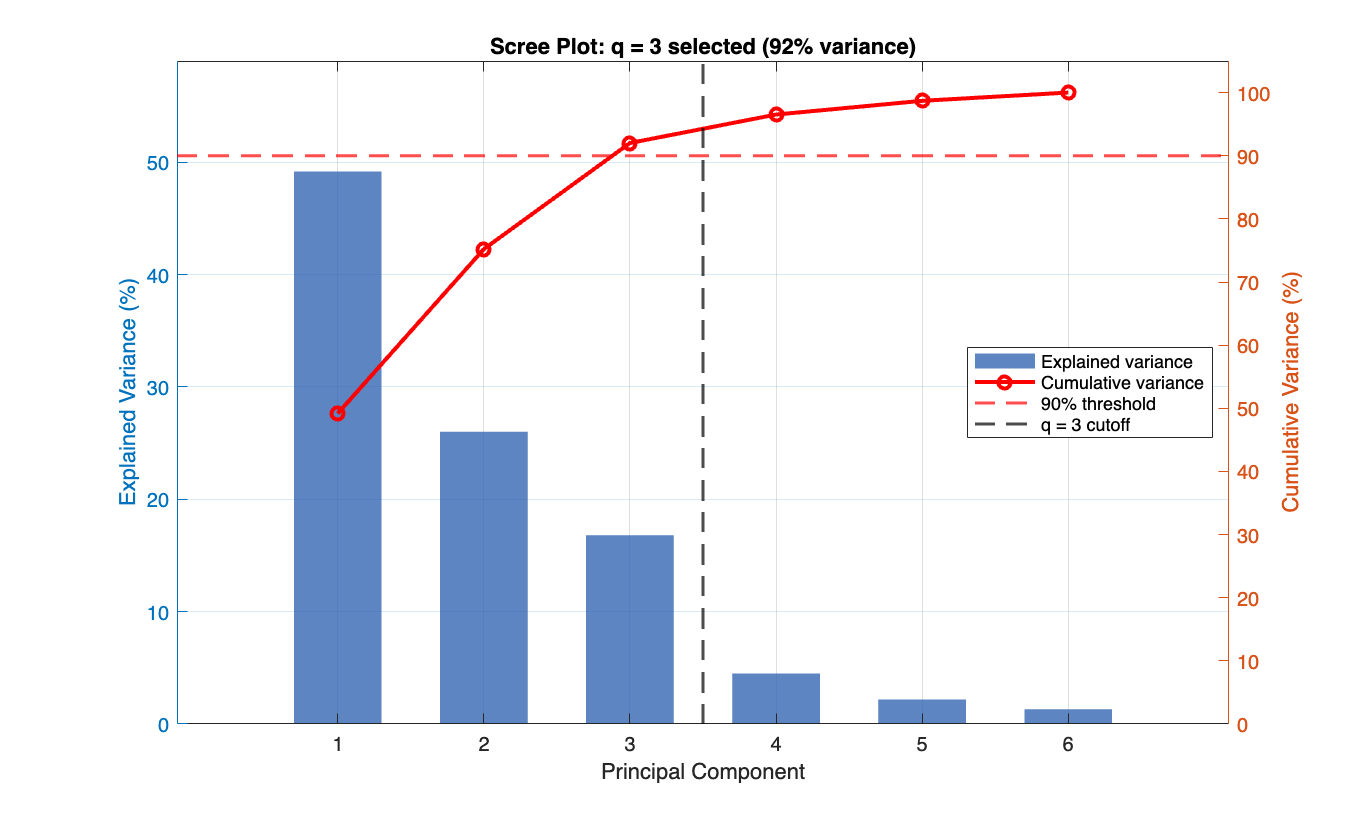

%2. Model Selection: Scree Plot

figure('Position', [100 100 700 420]); 

yyaxis left
b = bar(1:6, explained_variance, 0.6, 'FaceColor', [0.2 0.4 0.7], ...
    'FaceAlpha', 0.8, 'EdgeColor', 'none');
ylabel('Explained Variance (%)')
ylim([0 max(explained_variance)*1.2])

yyaxis right
p = plot(1:6, cum_variance, 'r-o', 'LineWidth', 2, 'MarkerSize', 6);
yl = yline(90, 'r--', 'LineWidth', 1.5);
ylabel('Cumulative Variance (%)')
ylim([0 105])

xl = xline(q + 0.5, 'k--', 'LineWidth', 1.5);
xlabel('Principal Component')
title('Scree Plot: q = 3 selected (92% variance)')
legend([b, p, yl, xl], ...
       {'Explained variance', 'Cumulative variance', '90% threshold', 'q = 3 cutoff'}, ...
       'Location', 'east')
grid on; box on
exportgraphics(gcf, fullfile(plots_dir, 'scree_plot.png'), 'Resolution', 300)

## 3. Biplot 2D: PC Loadings on Training Data

#### **The biplot shows how each sensor projects onto PC1 and PC2. Sensors with similar directions are correlated — they share the same latent variable.**

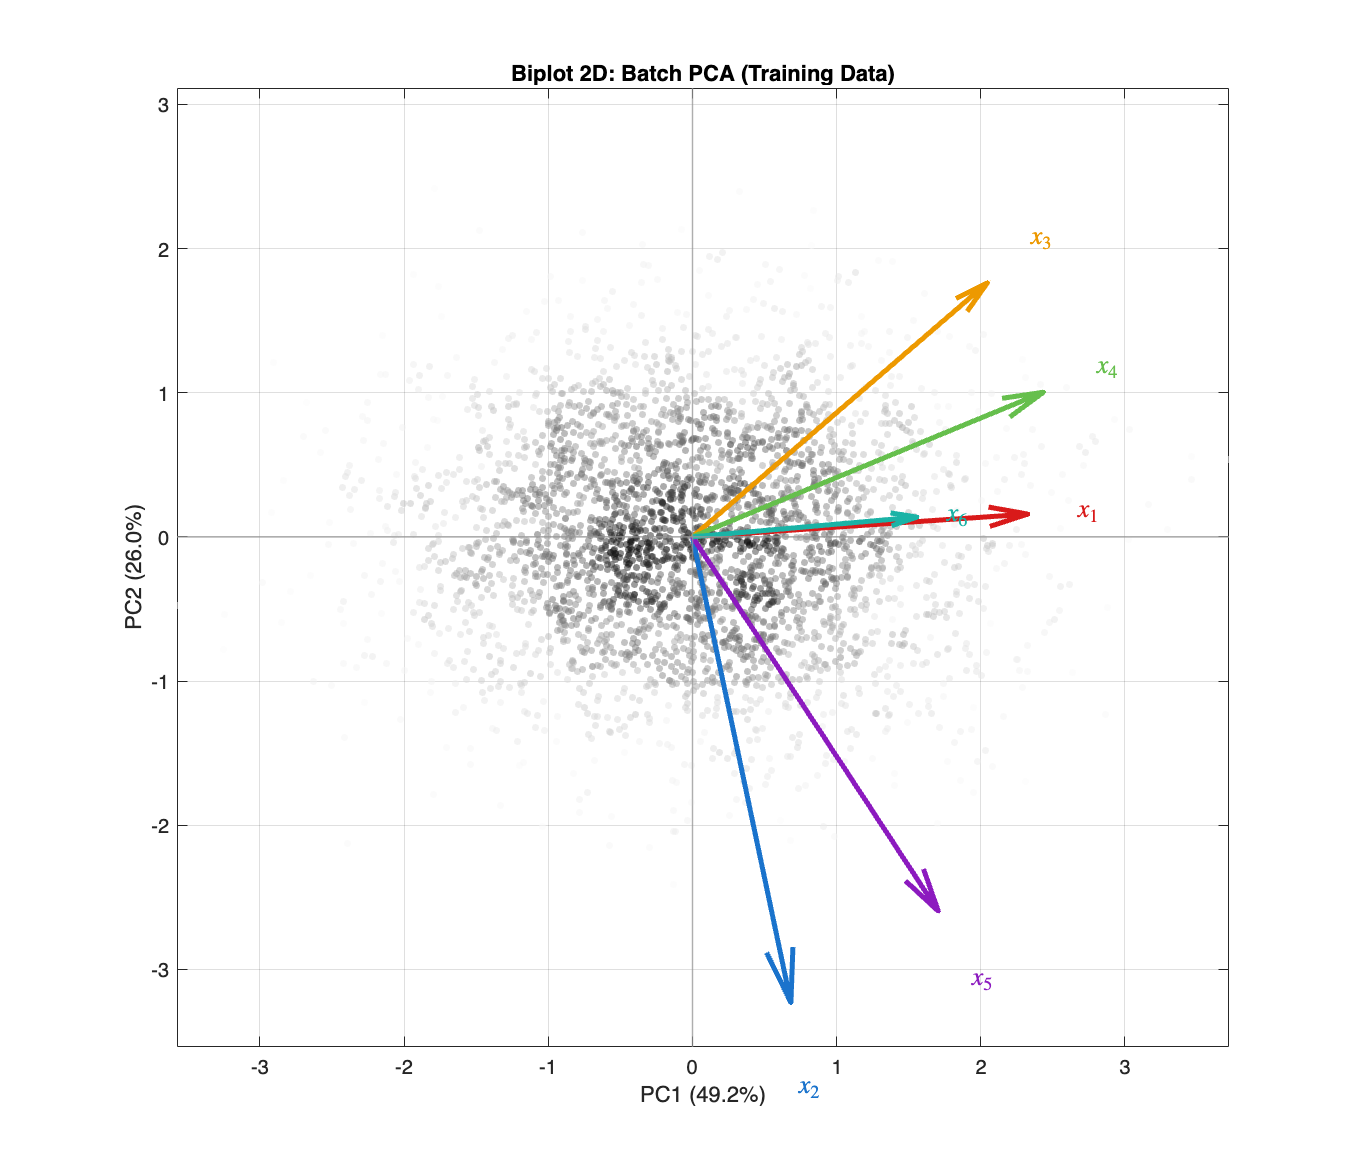

%% 3. Biplot 2D: PC Loadings on Training Data

loadings_2d = Vq(:, 1:2);
scores_2d   = Z * Vq(:,1:2);
sc_scale    = max(std(scores_2d));
scores_n    = scores_2d / sc_scale;
ld_scale    = max(max(abs(loadings_2d)));
loadings_n  = loadings_2d / ld_scale * 0.8 * max(max(abs(scores_n)));

figure('Position', [100 100 750 650])

idx_sub = randperm(N, 3000);
sc_sub  = scores_n(idx_sub, :);
n_bins  = 40;
[counts, xedge, yedge] = histcounts2(sc_sub(:,1), sc_sub(:,2), n_bins);
xc      = (xedge(1:end-1) + xedge(2:end)) / 2;
yc      = (yedge(1:end-1) + yedge(2:end)) / 2;
density = interp2(yc, xc, counts, sc_sub(:,2), sc_sub(:,1), 'linear', 0) + 0.1;

scatter(sc_sub(:,1), sc_sub(:,2), 12, density, 'filled', 'MarkerFaceAlpha', 0.5)
colormap(flipud(gray)); hold on

for j = 1:m
    quiver(0, 0, loadings_n(j,1), loadings_n(j,2), 0, ...
           'Color', arrow_cols(j,:), 'LineWidth', 2.5, ...
           'MaxHeadSize', 0.35, 'AutoScale', 'off')
    text(loadings_n(j,1)*1.18, loadings_n(j,2)*1.18, ...
         ['$' var_names{j} '$'], 'Interpreter', 'latex', ...
         'Color', arrow_cols(j,:), 'FontSize', 13, ...
         'FontWeight', 'bold', 'HorizontalAlignment', 'center')
end

xline(0, '-', 'Color', [0.6 0.6 0.6], 'LineWidth', 0.8)
yline(0, '-', 'Color', [0.6 0.6 0.6], 'LineWidth', 0.8)
xlabel(sprintf('PC1 (%.1f%%)', explained_variance(1)))
ylabel(sprintf('PC2 (%.1f%%)', explained_variance(2)))
title('Biplot 2D: Batch PCA (Training Data)')
grid on; box on; axis equal
exportgraphics(gcf, fullfile(plots_dir, 'biplot_2d.png'), 'Resolution', 300)

## 4. Batch PCA: Monitoring Analysis

#### **We apply the PCA model to 5 scenarios in increasing complexity:**

## **Monitoring Statistics**

Two complementary statistics are computed at each sample k.

### **Squared Prediction Error (SPE)**

Measures how well the current sample fits the PCA model: the residual in the orthogonal complement subspace:

### 
$$\text{SPE}_k = \|\tilde{x}_k - \hat{x}_k\|^2 = \tilde{x}_k^\top (I - V_q V_q^\top) \tilde{x}_k$$


**High SPE **→ the sample lies **outside** the model subspace → fault or model mismatch.

### **Hotelling's **$T^2$

Measures how far the sample is from the origin **inside** the model subspace:

### 
$$T^2_k = z_k^\top \Lambda_q^{-1} z_k, \qquad z_k = V_q^\top \tilde{x}_k \in \mathbb{R}^q$$


High $T^2$ → the sample is an outlier **within** the subspace → regime change or drift.

### **Control Limits**

#### 
$$\text{SPE}_{\text{lim}} = \hat{Q}_{0.95}(\text{SPE}_{\text{train}}), \qquad T^2_{\text{lim}} = \frac{q(N-1)(N+1)}{N(N-q)} F_{0.95}(q, N-q)$$


**Joint Interpretation**

%% 4. Batch PCA: Monitoring Analysis

% Contribution helper
contrib_fn = @(Z, k) (Z(k,:) - (Z(k,:) * Vq) * Vq').^2;


### **4a: Stationary**

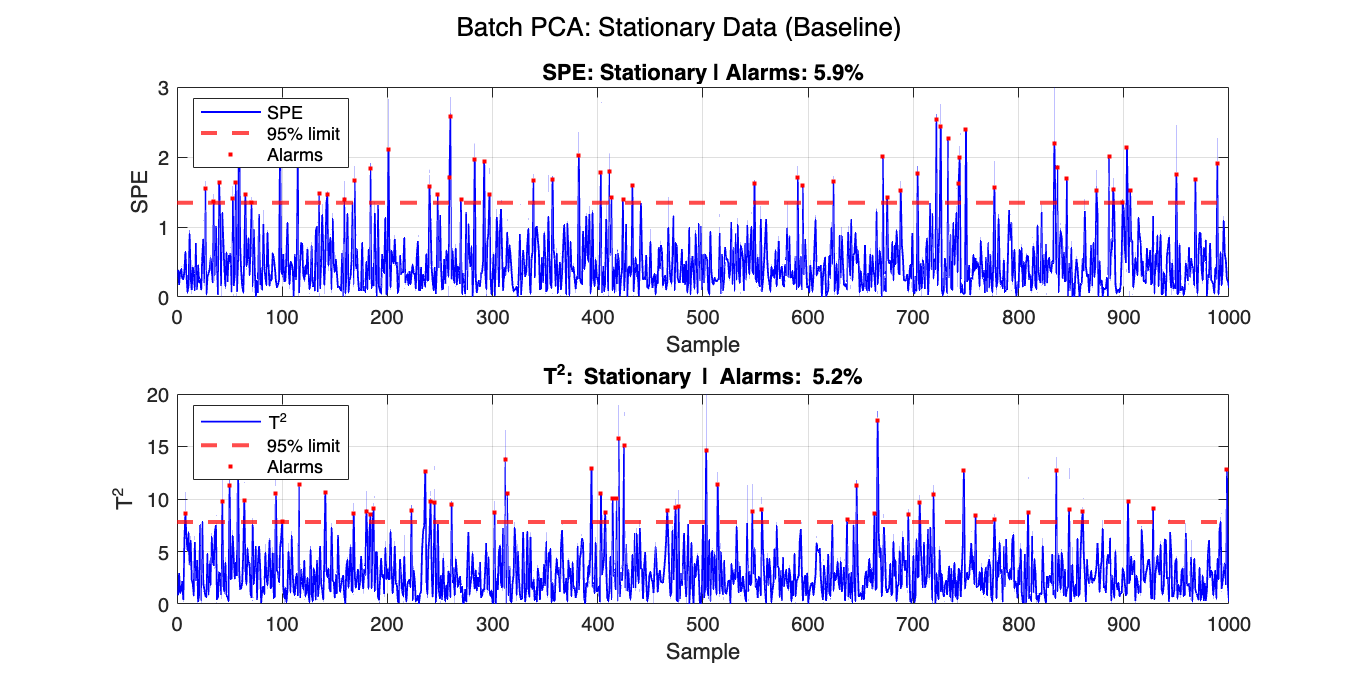

%% 4a: Stationary Baseline

Z_stat   = Z(1:1000,:);
sc_stat  = Z_stat * Vq;
SPE_stat = sum((Z_stat - sc_stat*Vq').^2, 2);
T2_stat  = sum((sc_stat ./ eigenvalues(1:q)') .* sc_stat, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
plot(SPE_stat, 'b-', 'LineWidth', 0.9)
yline(SPE_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_stat > SPE_lim);
plot(alarm_idx, SPE_stat(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Stationary | Alarms: %.1f%%', 100*mean(SPE_stat > SPE_lim)))
legend('SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
plot(T2_stat, 'b-', 'LineWidth', 0.9)
yline(T2_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_stat > T2_lim);
plot(alarm_idx, T2_stat(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Stationary | Alarms: %.1f%%', 100*mean(T2_stat > T2_lim)))
legend('T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('Batch PCA: Stationary Data (Baseline)', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4a_stationary.png'), 'Resolution', 300)

### 4b: Introducing drifts : Time Varying Data

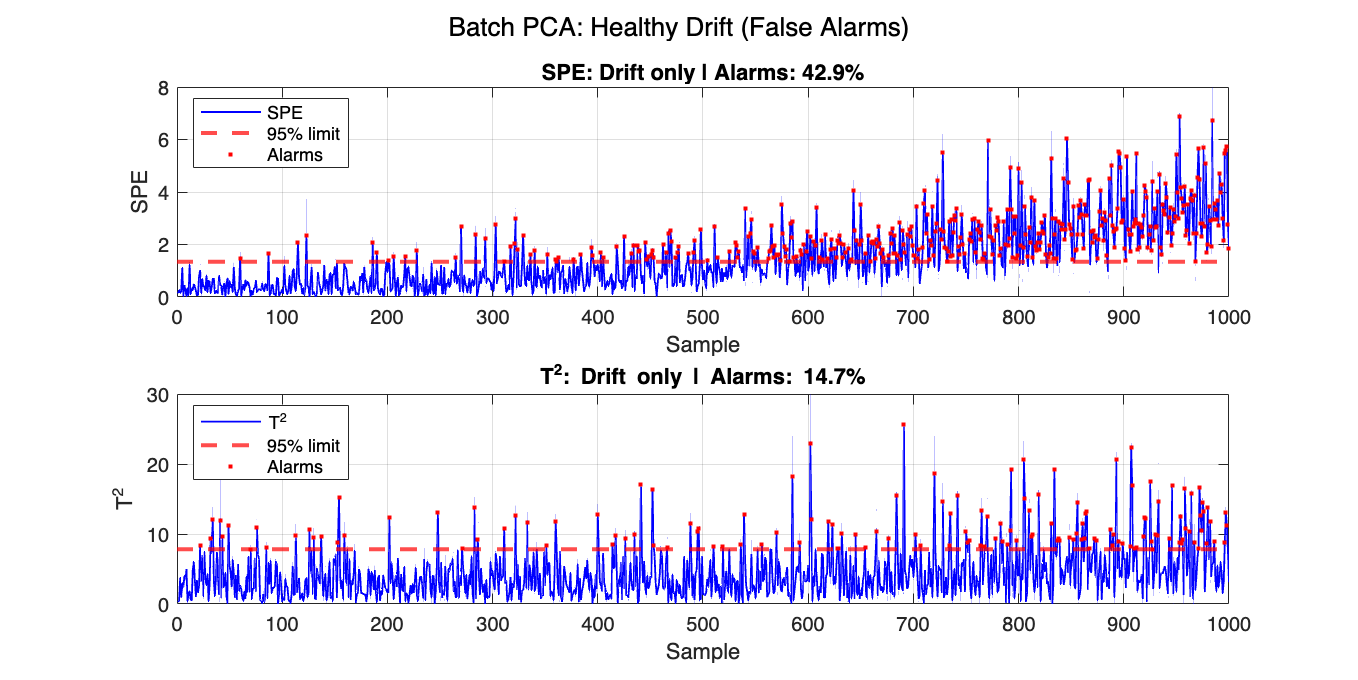

%% 4b: Drift Only

sc_drift  = Z_mon_drift * Vq;
SPE_drift = sum((Z_mon_drift - sc_drift*Vq').^2, 2);
T2_drift  = sum((sc_drift ./ eigenvalues(1:q)') .* sc_drift, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
plot(SPE_drift, 'b-', 'LineWidth', 0.9)
yline(SPE_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_drift > SPE_lim);
plot(alarm_idx, SPE_drift(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Drift only | Alarms: %.1f%%', 100*mean(SPE_drift > SPE_lim)))
legend('SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
plot(T2_drift, 'b-', 'LineWidth', 0.9)
yline(T2_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_drift > T2_lim);
plot(alarm_idx, T2_drift(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Drift only | Alarms: %.1f%%', 100*mean(T2_drift > T2_lim)))
legend('T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('Batch PCA: Healthy Drift (False Alarms)', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4b_drift.png'), 'Resolution', 300)

### 4c: Fault 1: Impulse on x5 (k=500-540)

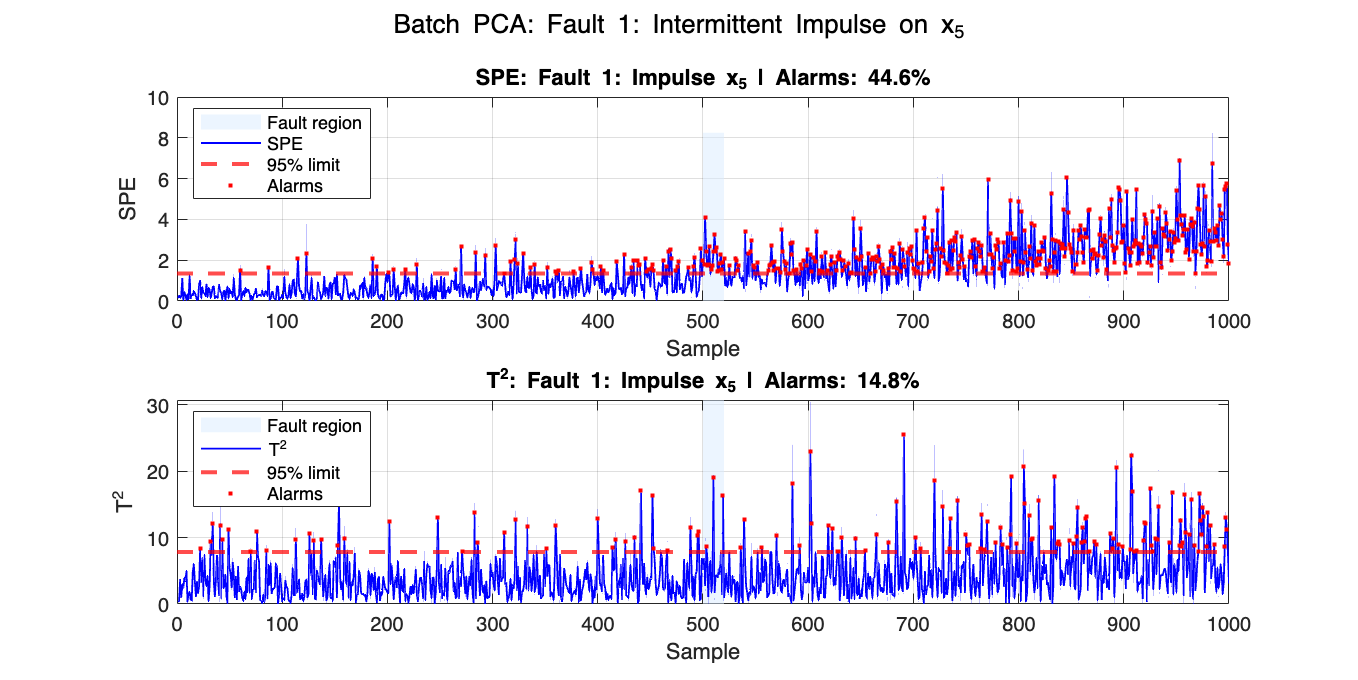


%% 4c: Fault 1: Impulse on x5 (k=500-540)

sc_f1  = Z_mon_f1 * Vq;
SPE_f1 = sum((Z_mon_f1 - sc_f1*Vq').^2, 2);
T2_f1  = sum((sc_f1 ./ eigenvalues(1:q)') .* sc_f1, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
fill([500 520 520 500], [0 0 max(SPE_f1)*1.2 max(SPE_f1)*1.2], ...
     fault_colors(1,:), 'EdgeColor','none','FaceAlpha',0.5)
plot(SPE_f1, 'b-', 'LineWidth', 0.9)
yline(SPE_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_f1 > SPE_lim);
plot(alarm_idx, SPE_f1(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Fault 1: Impulse x_5 | Alarms: %.1f%%', ...
      100*mean(SPE_f1 > SPE_lim)))
legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
fill([500 520 520 500], [0 0 max(T2_f1)*1.2 max(T2_f1)*1.2], ...
     fault_colors(1,:), 'EdgeColor','none','FaceAlpha',0.5)
plot(T2_f1, 'b-', 'LineWidth', 0.9)
yline(T2_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_f1 > T2_lim);
plot(alarm_idx, T2_f1(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Fault 1: Impulse x_5 | Alarms: %.1f%%', ...
      100*mean(T2_f1 > T2_lim)))
legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('Batch PCA: Fault 1: Intermittent Impulse on x_5', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4c_fault1.png'), 'Resolution', 300)

### 4d: Fault 2: Incipient (sinusoidal) on x4 (k=600-700)

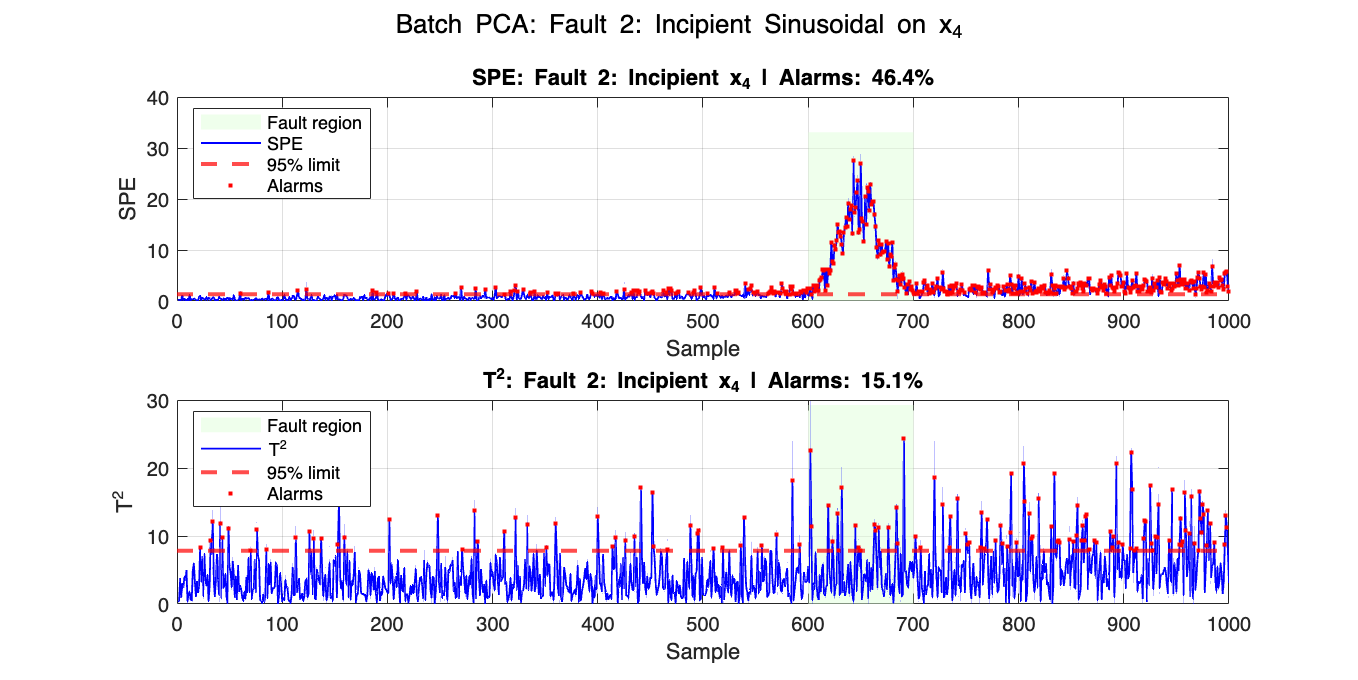


%% 4d: Fault 2: Incipient sinusoidal on x4 (k=600-700)

sc_f2  = Z_mon_f2 * Vq;
SPE_f2 = sum((Z_mon_f2 - sc_f2*Vq').^2, 2);
T2_f2  = sum((sc_f2 ./ eigenvalues(1:q)') .* sc_f2, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
fill([600 700 700 600], [0 0 max(SPE_f2)*1.2 max(SPE_f2)*1.2], ...
     fault_colors(2,:), 'EdgeColor','none','FaceAlpha',0.5)
plot(SPE_f2, 'b-', 'LineWidth', 0.9)
yline(SPE_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_f2 > SPE_lim);
plot(alarm_idx, SPE_f2(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Fault 2: Incipient x_4 | Alarms: %.1f%%', ...
      100*mean(SPE_f2 > SPE_lim)))
legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
fill([600 700 700 600], [0 0 max(T2_f2)*1.2 max(T2_f2)*1.2], ...
     fault_colors(2,:), 'EdgeColor','none','FaceAlpha',0.5)
plot(T2_f2, 'b-', 'LineWidth', 0.9)
yline(T2_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_f2 > T2_lim);
plot(alarm_idx, T2_f2(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Fault 2: Incipient x_4 | Alarms: %.1f%%', ...
      100*mean(T2_f2 > T2_lim)))
legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('Batch PCA: Fault 2: Incipient Sinusoidal on x_4', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4d_fault2.png'), 'Resolution', 300)

### 4e: Fault 3: Permanent step on x1 (k=800-1000)

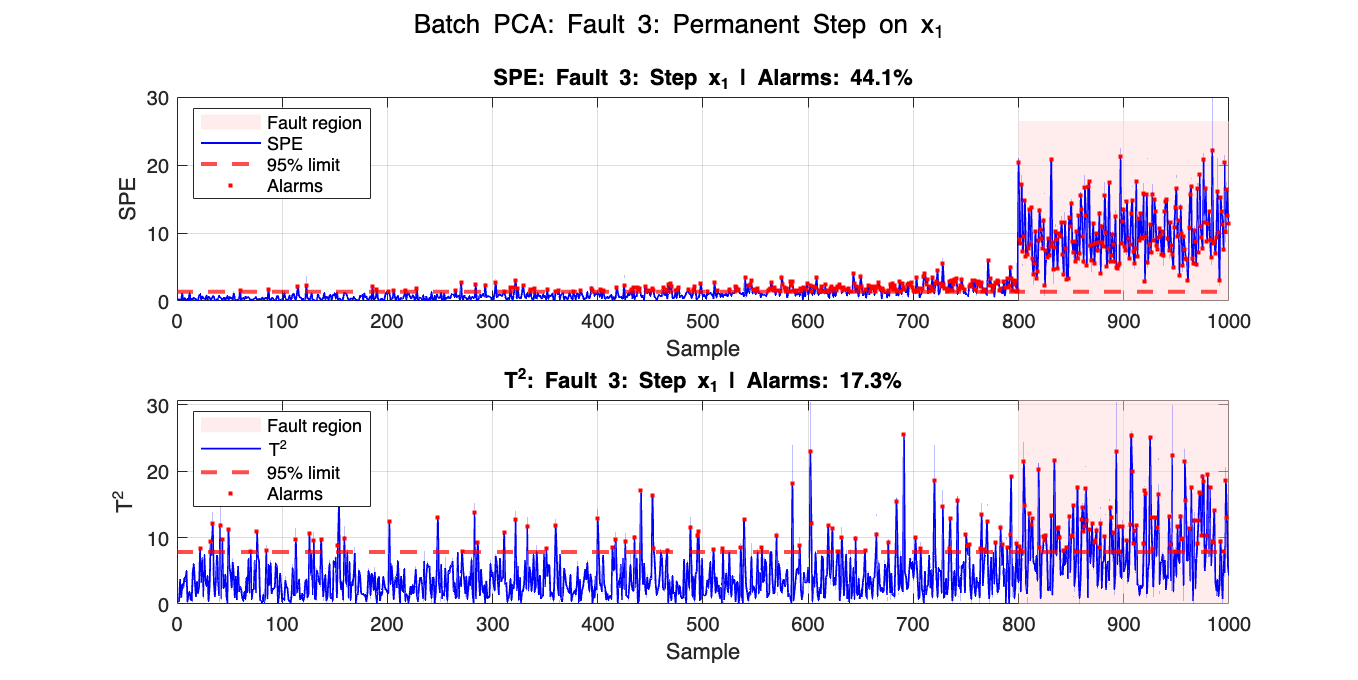


%% 4e: Fault 3: Permanent step on x1 (k=450-500)

sc_f3  = Z_mon_f3 * Vq;
SPE_f3 = sum((Z_mon_f3 - sc_f3*Vq').^2, 2);
T2_f3  = sum((sc_f3 ./ eigenvalues(1:q)') .* sc_f3, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
fill([800 1000 1000 800], [0 0 max(SPE_f3)*1.2 max(SPE_f3)*1.2], ...
     fault_colors(3,:), 'EdgeColor','none','FaceAlpha',0.5)
plot(SPE_f3, 'b-', 'LineWidth', 0.9)
yline(SPE_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_f3 > SPE_lim);
plot(alarm_idx, SPE_f3(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Fault 3: Step x_1 | Alarms: %.1f%%', ...
      100*mean(SPE_f3 > SPE_lim)))
legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
fill([800 1000 1000 800], [0 0 max(T2_f3)*1.2 max(T2_f3)*1.2], ...
     fault_colors(3,:), 'EdgeColor','none','FaceAlpha',0.5)
plot(T2_f3, 'b-', 'LineWidth', 0.9)
yline(T2_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_f3 > T2_lim);
plot(alarm_idx, T2_f3(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Fault 3: Step x_1 | Alarms: %.1f%%', ...
      100*mean(T2_f3 > T2_lim)))
legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('Batch PCA: Fault 3: Permanent Step on x_1', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4e_fault3.png'), 'Resolution', 300)

### 4f: Full Monitoring Dataset:  ALL FAULTS

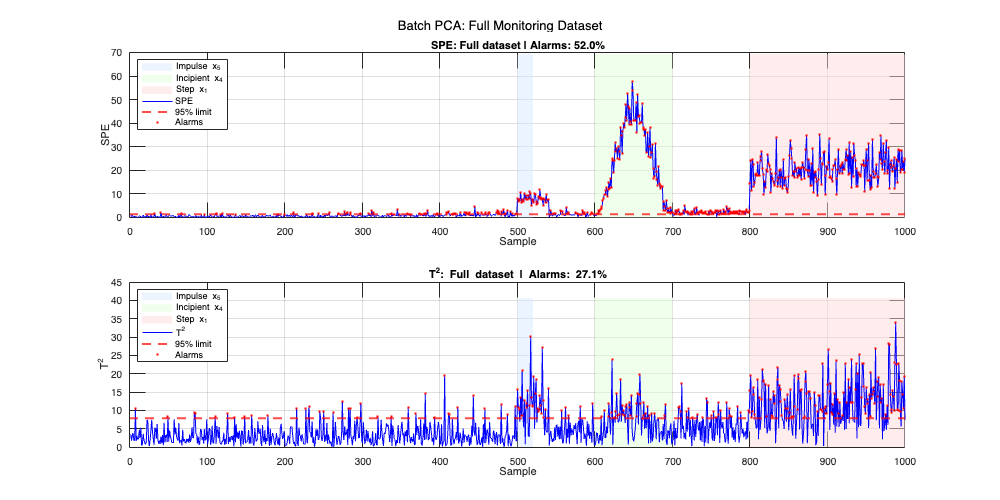

%% 4f: Full Monitoring Dataset

sc_mon  = Z_mon * Vq;
SPE_mon = sum((Z_mon - sc_mon*Vq').^2, 2);
T2_mon  = sum((sc_mon ./ eigenvalues(1:q)') .* sc_mon, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
for f = 1:3
    fill([fault_regions(f,1) fault_regions(f,2) ...
          fault_regions(f,2) fault_regions(f,1)], ...
         [0 0 max(SPE_mon)*1.2 max(SPE_mon)*1.2], ...
         fault_colors(f,:), 'EdgeColor','none','FaceAlpha',0.5)
end
plot(SPE_mon, 'b-', 'LineWidth', 0.9)
yline(SPE_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_mon > SPE_lim);
plot(alarm_idx, SPE_mon(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Full dataset | Alarms: %.1f%%', ...
      100*mean(SPE_mon > SPE_lim)))
legend('Impulse x_5','Incipient x_4','Step x_1', ...
       'SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
for f = 1:3
    fill([fault_regions(f,1) fault_regions(f,2) ...
          fault_regions(f,2) fault_regions(f,1)], ...
         [0 0 max(T2_mon)*1.2 max(T2_mon)*1.2], ...
         fault_colors(f,:), 'EdgeColor','none','FaceAlpha',0.5)
end
plot(T2_mon, 'b-', 'LineWidth', 0.9)
yline(T2_lim, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_mon > T2_lim);
plot(alarm_idx, T2_mon(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Full dataset | Alarms: %.1f%%', ...
      100*mean(T2_mon > T2_lim)))
legend('Impulse x_5','Incipient x_4','Step x_1', ...
       'T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('Batch PCA: Full Monitoring Dataset', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4f_full.png'), 'Resolution', 300)

## 4g: Contribution Plots per Fault Type

#### **Fault Isolation: SPE Contribution Plot**

#### When SPE exceeds the control limit, we can assume that a fault occurred but we don't know which sensor is coming from.

#### The contribution plot decomposes SPE variable by variable:

#### 
$$\text{SPE} = \sum_{i=1}^{m} e_i^2, \qquad e_i = \tilde{x}_i - \hat{x}_i$$


#### where $e_i $ is the reconstruction error of sensor i. The percentage contribution of each sensor is:

#### 
$$\text{SPE} = \sum_{i=1}^{m} e_i^2, \qquad e_i = \tilde{x}_i - \hat{x}_i$$


#### A uniform contribution baseline is $100/m=16.7%100/m = 16.7\% 100/m=16.7%$. A sensor significantly above this threshold is the primary fault source.

#### **Interpretation:**

#### Impulsive fault → x_5  dominates

#### Incipient fault → x_4 dominates

#### Step fault → x_1  dominates

#### This moves from **fault detection** (SPE alarm) to **fault isolation** (which sensor): the FDI pipeline.

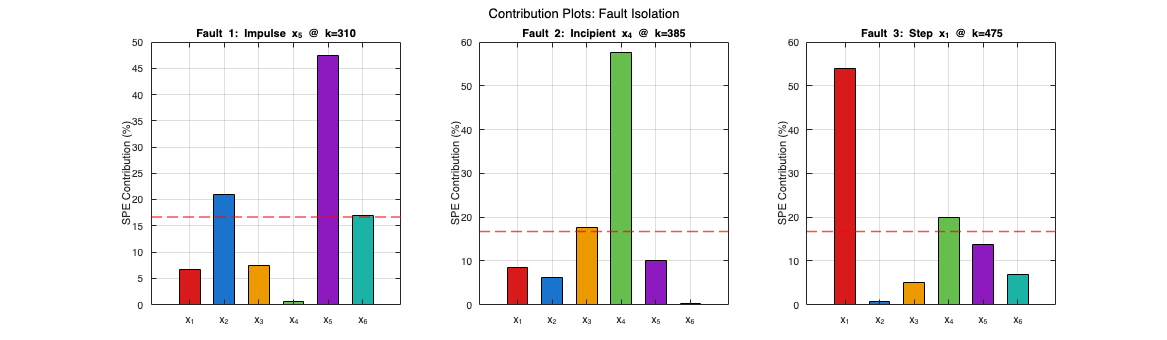


%% 4g: Contribution Plots per Fault Type

figure('Position', [100 100 1200 350])

datasets  = {Z_mon_f1, Z_mon_f2, Z_mon_f3};
k_samples = [510, 650, 900];
titles    = {'Fault 1: Impulse x_5 @ k=310', ...
             'Fault 2: Incipient x_4 @ k=385', ...
             'Fault 3: Step x_1 @ k=475'};

for f = 1:3
    subplot(1,3,f)
    c   = contrib_fn(datasets{f}, k_samples(f));
    b_h = bar(1:m, 100*c/sum(c), 0.6);
    b_h.FaceColor = 'flat';
    for j = 1:m; b_h.CData(j,:) = arrow_cols(j,:); end
    yline(100/m, 'r--', 'LineWidth', 1.5)
    xticks(1:m); xticklabels(var_names)
    ylabel('SPE Contribution (%)')
    title(titles{f})
    grid on; box on
end

sgtitle('Contribution Plots: Fault Isolation', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'pca_4g_contributions.png'), 'Resolution', 300)

## 5. Performance Metrics Batch PCA

%% 5. Performance Metrics: Batch PCA

GT_f1 = zeros(N2,1); GT_f1(500:520)  = 1;
GT_f2 = zeros(N2,1); GT_f2(600:700)  = 1;
GT_f3 = zeros(N2,1); GT_f3(800:1000) = 1;

datasets    = {Z_mon_f1,  Z_mon_f2,  Z_mon_f3};
GT          = {GT_f1,     GT_f2,     GT_f3};
SPE_vecs    = {SPE_f1,    SPE_f2,    SPE_f3};
T2_vecs     = {T2_f1,     T2_f2,     T2_f3};
fault_names = {'Fault 1: Impulse x_5', 'Fault 2: Incipient x_4', 'Fault 3: Step x_1'};

Prec_SPE = zeros(3,1); Rec_SPE = zeros(3,1); F1_SPE = zeros(3,1);
Prec_T2  = zeros(3,1); Rec_T2  = zeros(3,1); F1_T2  = zeros(3,1);

for f = 1:3
    gt  = GT{f};
    spe = SPE_vecs{f};
    t2  = T2_vecs{f};

    % SPE
    TP = sum(spe(gt==1) > SPE_lim);
    FP = sum(spe(gt==0) > SPE_lim);
    FN = sum(spe(gt==1) <= SPE_lim);
    Prec_SPE(f) = TP / max(TP+FP, 1);
    Rec_SPE(f)  = TP / max(TP+FN, 1);
    F1_SPE(f)   = 2*Prec_SPE(f)*Rec_SPE(f) / max(Prec_SPE(f)+Rec_SPE(f), 1e-10);

    % T²
    TP = sum(t2(gt==1) > T2_lim);
    FP = sum(t2(gt==0) > T2_lim);
    FN = sum(t2(gt==1) <= T2_lim);
    Prec_T2(f) = TP / max(TP+FP, 1);
    Rec_T2(f)  = TP / max(TP+FN, 1);
    F1_T2(f)   = 2*Prec_T2(f)*Rec_T2(f) / max(Prec_T2(f)+Rec_T2(f), 1e-10);
end

T_metrics = table(fault_names', ...
    round(Prec_SPE,3), round(Rec_SPE,3), round(F1_SPE,3), ...
    round(Prec_T2,3),  round(Rec_T2,3),  round(F1_T2,3),  ...
    'VariableNames', {'Fault', ...
    'SPE_Precision','SPE_Recall','SPE_F1', ...
    'T2_Precision', 'T2_Recall', 'T2_F1'});

disp('--- Batch PCA Performance Metrics ---')

--- Batch PCA Performance Metrics ---


disp(T_metrics)

              Fault               SPE_Precision    SPE_Recall    SPE_F1    T2_Precision    T2_Recall    T2_F1
    __________________________    _____________    __________    ______    ____________    _________    _____

    {'Fault 1: Impulse x_5'  }        0.042          0.905        0.08        0.031          0.238      0.056
    {'Fault 2: Incipient x_4'}        0.193          0.921       0.319        0.085          0.129      0.102
    {'Fault 3: Step x_1'     }         0.44              1       0.611        0.532          0.532      0.532

